# Optical Sphere 

This script models optical refraction on a spherical lens of constant refractive index (n_glass).

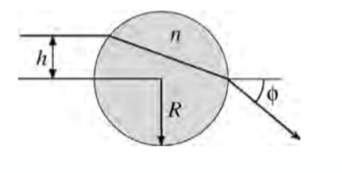

%Define General parameters
R = 2;      %Radius
h = R/2;    %Initial height 
n_air = 1;      %Refraction index
n_glass = 1.52; %Refraction index

% Define sphere
x1 = @(y) - sqrt(R^2-y.^2); %Concave
x2 = @(y)  sqrt(R^2-y.^2);  %Convex

%Define coordinates of incident ray
xi1 = x1(h); 

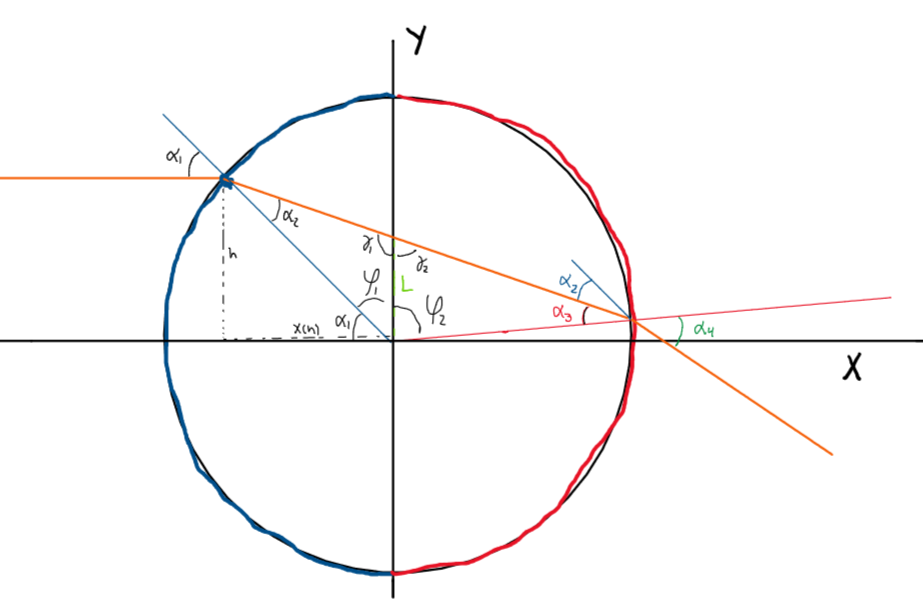

alpha1 = asin(h/R);
alpha2 = asin(sin(alpha1)/n_glass)

alpha2 = 0.3352

phi1 = pi/2 - alpha1; 
gamma1 = pi - alpha2 - phi1;
gamma2 = pi - gamma1; 
L = R*sin(alpha2)/sin(gamma1);
alpha3 = asin(L*sin(gamma2)/R); 
phi2 = pi - alpha3 - gamma2; 
alpha4 = asin(n_glass*sin(alpha3)/n_air);

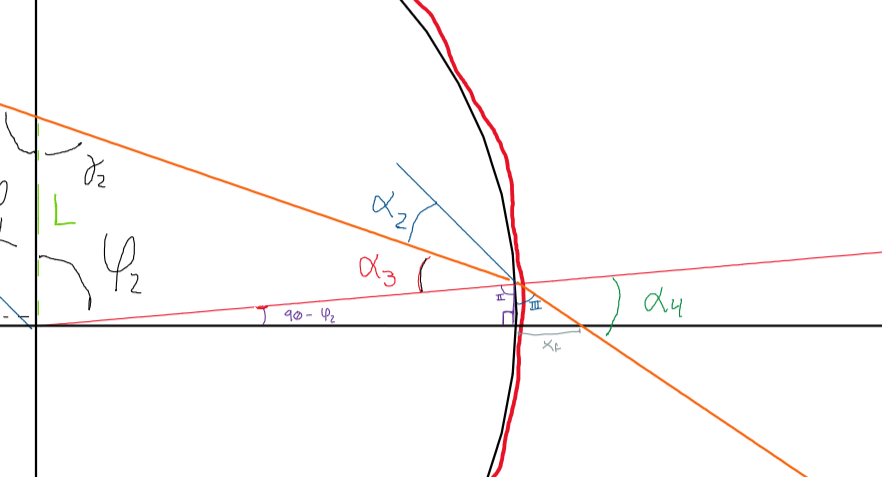

yi2 = R * sin(pi/2 - phi2);

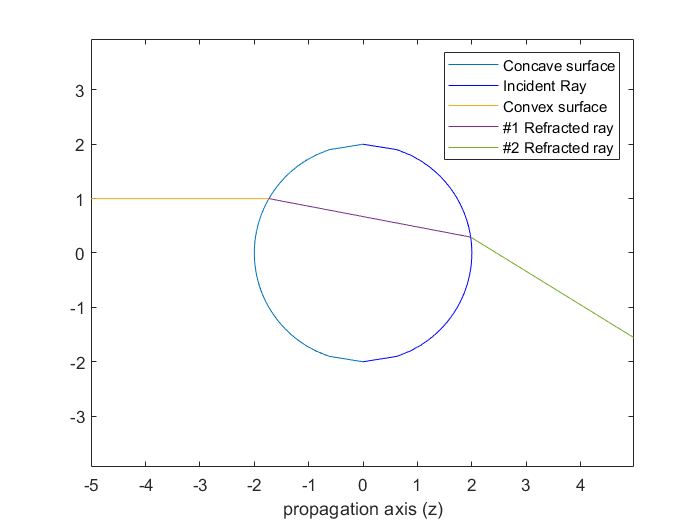

III = 180 - phi2 - alpha4; 
xf = 3; 
yf = xf/tan(III);

%Plot Sphere
plot(x1(-R:0.1:R),[-R:0.1:R],x2(-R:0.1:R),[-R:0.1:R],"b")
hold on
%Plot incident ray
plot([-5,x1(h)],[h,h])
%Plot inside ray
plot([x1(h),x2(yi2)],[h,yi2])
%Plot final ray
plot([x2(yi2),x2(yi2)+xf],[yi2,yi2+yf])
axis equal
xlabel("propagation axis (z)")
legend("Concave surface","Incident Ray", "Convex surface","#1 Refracted ray","#2 Refracted ray")
hold off